clear all
clc
%set variables
Model.Nx=3000;                      % number of grid points in the x (row) direction
Model.Ny=1800;                       % number of grid points in the y (column) direction
Model.dx= 3e-05;                % grid point spacing in the x direction [m]
Model.dy= 3e-05;                % grid point spacing in the y direction [m]
Model.sample_rate_model=1e9/10;        %[HZ]
Model.sample_rate_exp=1e9/5;          %[HZ]
Model.amplitude=1;
Medium.speed_of_sound=1480; %speed of sound in a homogeneous medium should be the same as the model[m/s]
Medium.sound_speed_sample=1490;%speed of sound inside the sample
Medium.density_sample=1040;%density of the sample
Medium.absorption=206;               %[1/m]
% Medium.absorptionW=80;
% Geometry.water_length_before=0.008;
% Geometry.water_length_after=0.005;
Geometry.l=0.019;                    %diameter of transducer
Geometry.sensor_thikness=3.75e-05; %thikness of the sensor
Geometry.distance=0.02645;%distance between the back of cuvette and transducer[m].
Geometry.cuvette_length=0.0055;%Width of the sample inside the cuvette
Geometry.cuvette_face=5e-3;   %thickness of PMMA layer
Geometry.cuvette_Gasket=0.5e-3   % thickness of silicon rubber

Geometry = struct with fields:
                  l: 0.0190
    sensor_thikness: 3.7500e-05
           distance: 0.0265
     cuvette_length: 0.0055
       cuvette_face: 0.0050
     cuvette_Gasket: 5.0000e-04


Geometry.cuvette_diameter=0.018; % diameter of the sample inside the cylindrical cuvette.[m]
Geometry.a=1.16;

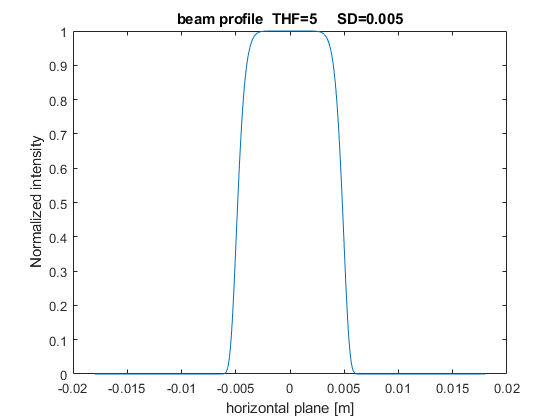

%set beam profile.
Geometry.q=0.005; %standard deviation 
Geometry.p=5;
      % flat top factor
x_beam=-0.018:0.00001:0.018;
y_beam=exp(-((x_beam.^2)/(Geometry.q^2)).^Geometry.p);
figure(12)
plot(x_beam,y_beam)
title(['beam profile  THF=',num2str(Geometry.p),'     SD=',num2str(Geometry.q)]);
xlabel('horizontal plane [m]')
ylabel('Normalized intensity')

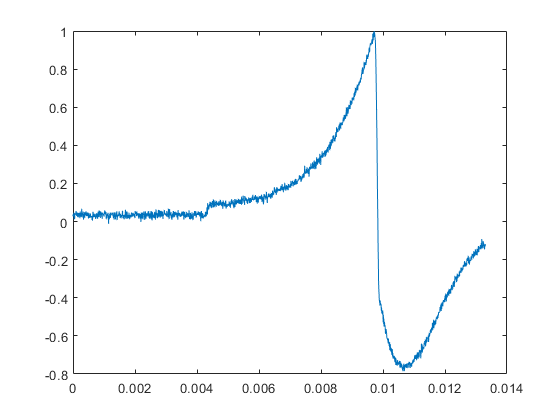

%read experimental data from TDMS files
filename = 'C:\Users\Marzieh\Documents\Marzieh\Data\19.07.2023\CUSO40.25M.19.7.2023_red_ND0.6_test1_20230719_93503_327.tdms';
my_tdms_struct = TDMS_getStruct(filename,1);
channels=my_tdms_struct.M800D0;
S_exp=Mean_Tdms(channels);
figure(20)
plot(0:1/Model.sample_rate_exp*Medium.speed_of_sound:(length(S_exp)-1)*Medium.speed_of_sound/Model.sample_rate_exp,S_exp/max(S_exp(:)))

%S_exp=smoothdata(S_exp,'movmean',50);

plot(0:1/Model.sample_rate_exp*Medium.speed_of_sound:(length(S_exp)-1)*Medium.speed_of_sound/Model.sample_rate_exp,S_exp/max(S_exp(:)))
S_exp=smoothdata(S_exp,'movmean',50);

%read experimental data from excel files
[number,string,raw] = xlsread('C:\Users\Marzieh\Documents\Marzieh\Data\\27.08.2021\CUSO4_0.25M_680nm_low.xlsx'); 
S_exp=number(1:1800)';
plot(0:1/Model.sample_rate_exp:(length(S_exp)-1)/Model.sample_rate_exp,S_exp)

Running k-Wave simulation...
  start time: 30-Aug-2023 12:32:29
  reference sound speed: 1480m/s
  dt: 10ns, t_end: 50us, time steps: 5001
  input grid size: 3000 by 1800 grid points (90 by 54mm)
  maximum supported frequency: 24.6667MHz
  smoothing p0 distribution...
  casting variables to gpuArray type...
  precomputation completed in 4.6s
  starting time loop...
  estimated simulation time 6min 54.7829s...
  GPU memory used: 3.2431 GB (of 11.9998 GB)
  simulation completed in 8min 20.5279s
  total computation time 8min 25.187s


sensor_data_integrated =    1.0e-17 *

    0.0003   -0.0173   -0.0438   -0.0678   -0.0799   -0.0769   -0.0467   -0.0170   -0.0075   -0.0479   -0.0811   -0.0671   -0.0504   -0.0140   -0.0451   -0.0773   -0.0719   -0.0454   -0.0178   -0.0452   -0.1337   -0.1522   -0.0761    0.0070   -0.0181   -0.1077   -0.1124   -0.0755   -0.0474   -0.0989   -0.1560   -0.1381   -0.0245    0.0102   -0.1006   -0.1993   -0.0930    0.0774    0.0676   -0.0910   -0.1922   -0.1280   -0.0334   -0.0144   -0.0430   -0.0595   -0.0407    0.0116    0.0336    0.0229


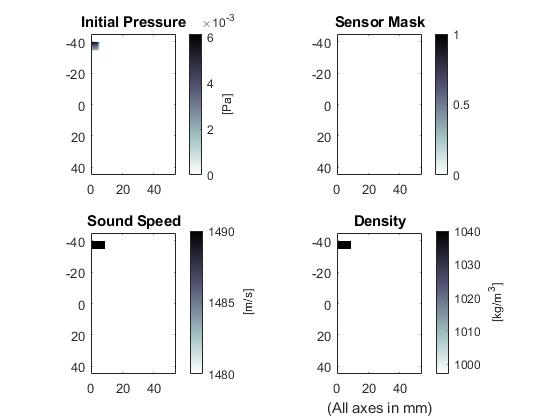

global source;
global sensor_data;
global sensor;
global medium;
S_model_2=forward_homogeneous(Model, Medium, Geometry);

%Run the forward model to get simulated data.
medium_m=medium;
sensor_m=sensor;
source_m=source;
data_m=sensor_data;
%signal_m=S_model;


[S_model_processed, S_exp_processed] =processsignals_alternative(S_model,S_exp, Model, Medium, Geometry);

Undefined function or variable 'S_model'.

%process both experimental and simulated data to compare them. 
%steps of the process:
%1_ match sample rates of experimental and simulated data.
%3_ correct offset of experimental signal.
%4_ match time delays of experimental and simulated signals
%5_ normalizing simulated data based on experimental data.


%Error calculation
global X_exp_pos
global X_model_pos
global Y_exp_pos
global Y_model_pos

RMSE_total=sqrt(mean((S_exp_processed-S_model_processed).^2))/sqrt(mean((S_exp_processed).^2))*100;
RMSE_pos=sqrt(mean((Y_exp_pos-Y_model_pos).^2))/sqrt(mean((Y_exp_pos).^2))*100;
peak_to_peak_amplitude=abs(min(S_exp_processed(:))-min(S_model_processed(:)))/abs(min(S_exp_processed(:)))*100;



%visualizatoin
global X_exp
global X_model

global p_0
[fitresult,gof,coeffvals] =fitexpo(X_exp_pos,Y_exp_pos);
[fitresultm,gofm,coeffvalsm] =fitexpo(X_model_pos,Y_model_pos);

figure(11)
plot(X_model, S_model_processed);
hold on
plot(X_exp, S_exp_processed/0.8);



ylabel('PA signal');
xlabel('X [m]');
title({['RMSE total=',num2str(RMSE_total),'%             RMSE positive part=',num2str(RMSE_pos),'%'],...
    ['peak to peak amplitude error= ',num2str(peak_to_peak_amplitude),'%...' ...
    '      absorption coefficient=',num2str(Medium.absorption)]});


legend('Simulated PA signal','Experimental PA signal', 'Location','southeast')



figure(10)
plot(X_exp_pos,Y_exp_pos)
hold on
plot(X_model_pos,Y_model_pos)
%plot(X_exp_pos,fitresult(X_exp_pos))
%plot(X_model_pos,fitresultm(X_model_pos))
%title({['absorption coefficient fitted exp=',num2str(coeffvals(1,2))],...
   % ['absorption coefficient fitted model=',num2str(coeffvalsm(1,2))]})
%legend('experimental data','simulated data', 'experimental fit', 'simulated fit')


figure(2)
plot(X_exp_pos,Y_exp_pos/max(Y_exp_pos(:)))
hold on
plot(X_model_pos,Y_model_pos/max(Y_model_pos(:)))
title('Normalized PA Signal')
legend('experimental data','simulated data')
ylabel('PA signal');
xlabel('X [m]');